## 6. Treating color images

Complete the script "exercise6.m" to implement the following steps: Given the images hand.jpg (Figure 3(left)) and mapfre.jpg (Figure 3(middle)), create the function fuseImg(), which implements the following points:

The function fuseImg executed as follows, runs the steps detailed in the next subsections.

fuseImg()

The implementation of the function can be found in the Defined Function section at the end of the report.

1. Open hand.jpg and convert it in gray scale image.

HAND = imread('images/hand.jpg');
MAPFRE = imread('images/mapfre.jpg');
grayscaleHand = rgb2gray(HAND);

2. Perform a binarization to obtain a binary image of 2 regions: the hand (called foreground) and the rest (called background). Create the inverse binary image changing the areas of foreground and background.

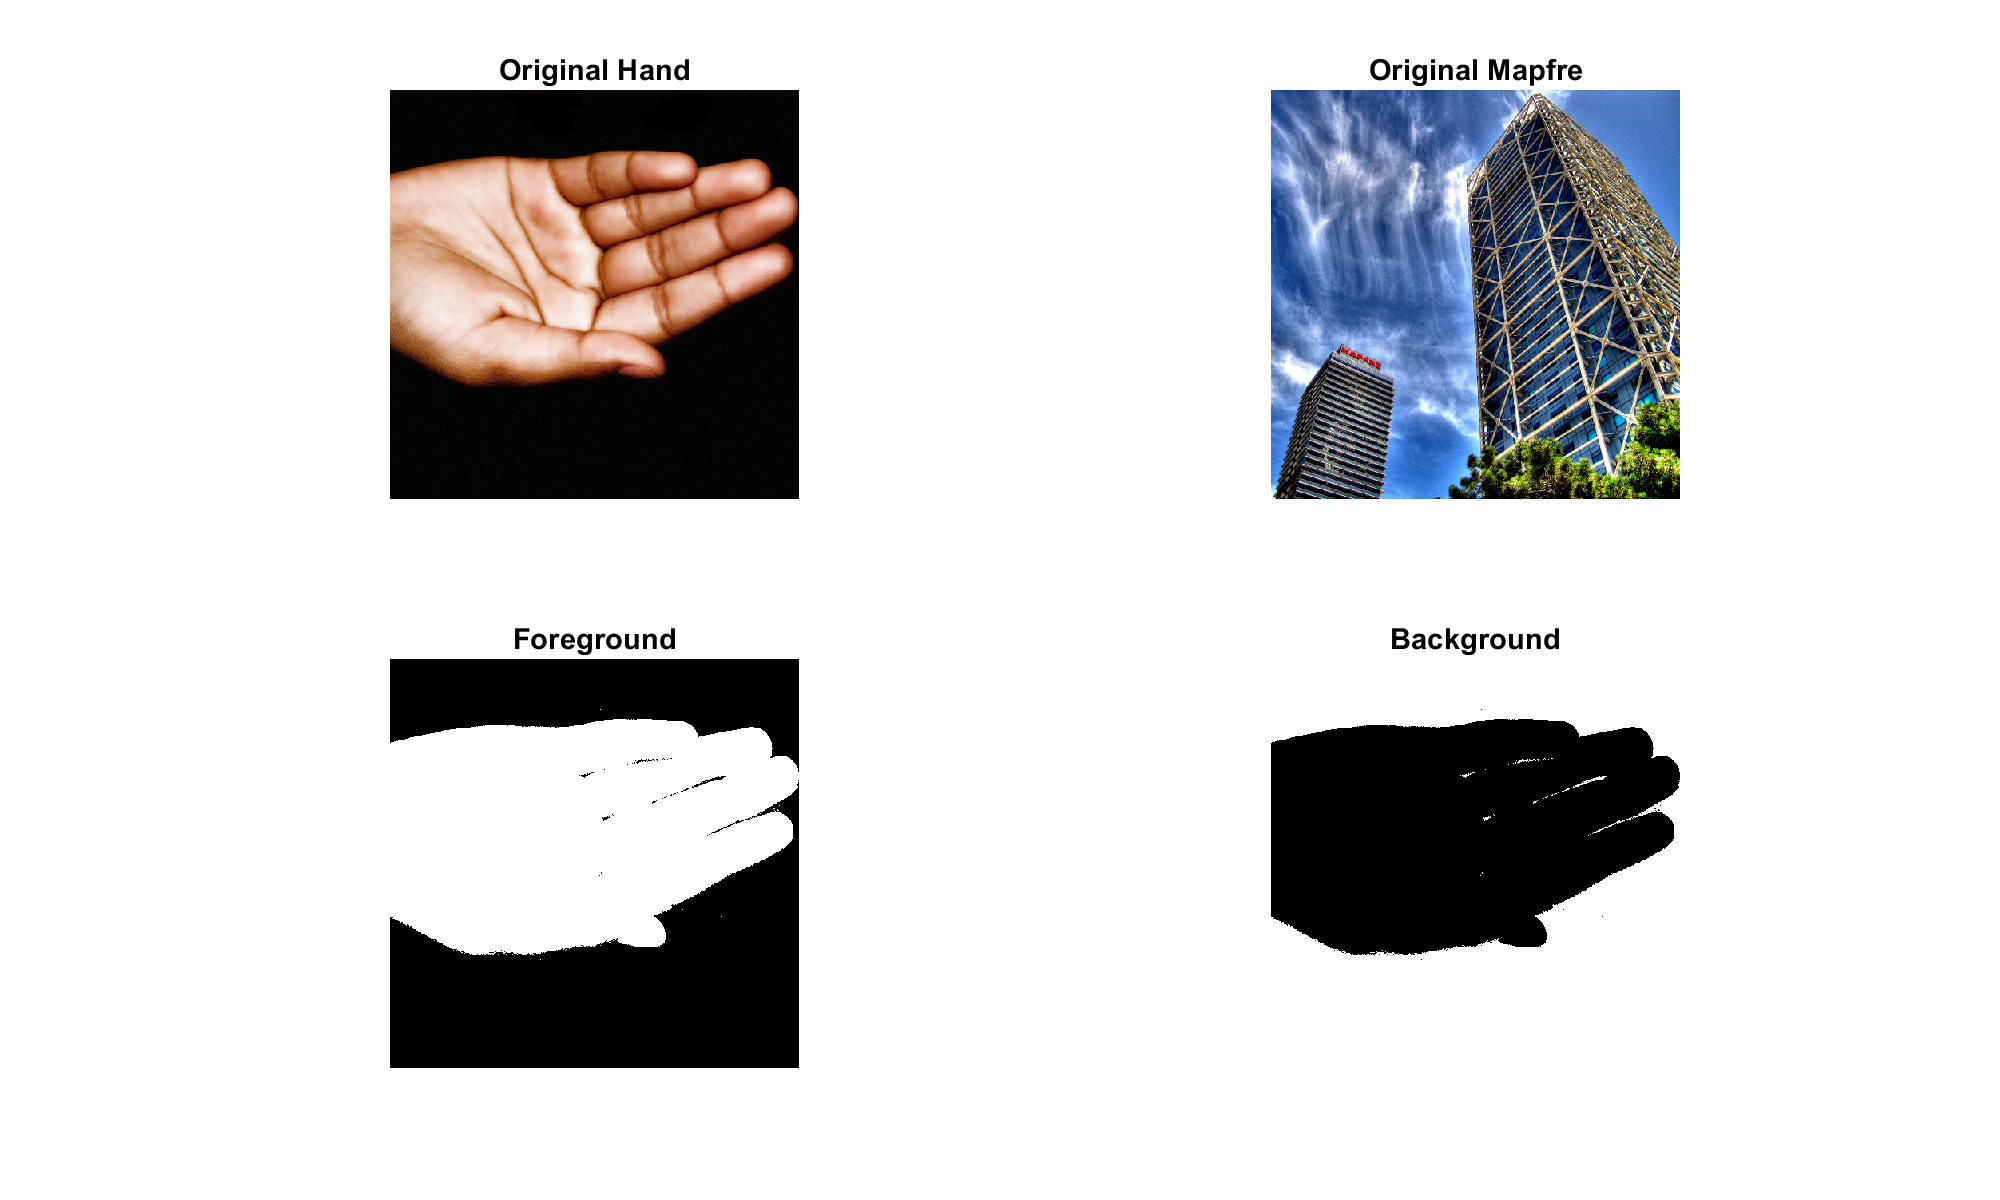

th = 20;
foregroundHand = grayscaleHand >= th;
backgroundHand = not(foregroundHand);

set(gcf,'Position',[0 0 1000 600]), ...
subplot(2,2,1), imshow(HAND), title("Original Hand"), ...
subplot(2,2,2), imshow(MAPFRE), title("Original Mapfre"), ...
subplot(2,2,3), imshow(foregroundHand), title("Foreground"), ...
subplot(2,2,4), imshow(backgroundHand), title("Background");

3. Use the binary matrices created in (2) to merge the images hand and mapfre (Fig. 3(right))

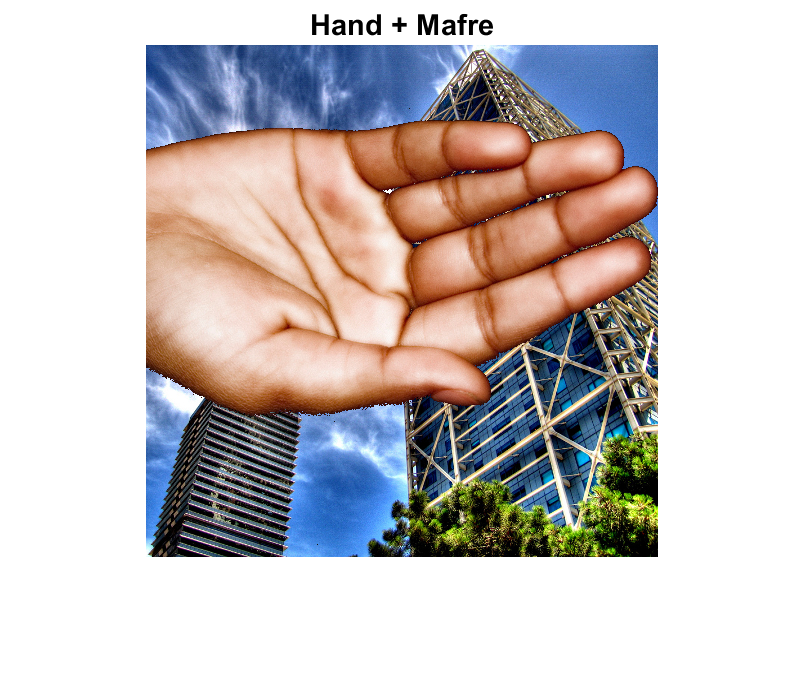

background = MAPFRE.*uint8(backgroundHand);
foreground = HAND.*uint8(foregroundHand);
handMapfre = background + foreground;
subplot(1,1,1), imshow(handMapfre), title("Hand + Mafre");

4. Save the image as hand_mapfre.jpg.

imwrite(handMapfre, 'hand_mapfre.jpg');

## Defined Functions

function fuseImg()
%fuseImg Function that executes steps 1 to 4 of Exercise 6

% 1 Read Input
HAND = imread('images/hand.jpg');
MAPFRE = imread('images/mapfre.jpg');
grayscaleHand = rgb2gray(HAND);

% 2 Binarization
th = 20;
foregroundHand = grayscaleHand >= th;
backgroundHand = not(foregroundHand);

% 3 Merge
background = MAPFRE.*uint8(backgroundHand);
foreground = HAND.*uint8(foregroundHand);
handMapfre = background + foreground;

% 4 Save output
imwrite(handMapfre, 'hand_mapfre.jpg');

end